EE 216 Communications Lab 16-QAM

Rishabh Pomaje-210020036

Ganesh Panduranga Karamsetty-210020009

Generating random data :(Modulation)

%number of symbols
n=10^4 ;
%generating 4-bits simultanously
d1=randi(2,n,1) ;
b1=d1-1 ;
d2=randi(2,n,1) ;
b2=d2-1 ;
d3=randi(2,n,1) ;
b3=d3-1 ;
d4=randi(2,n,1) ;
b4=d4-1 ;
%array to store 4 bits together
for i=1:n 
    data(i,1)=b1(i) ;
    data(i,2)=b2(i) ;
    data(i,3)=b3(i) ;
    data(i,4)=b4(i) ;
end
disp('Random Data generated:')

Random Data generated:


data

data =      0     1     1     1
     1     0     0     1
     1     0     1     0
     0     0     1     0
     1     1     1     1
     0     0     1     1
     0     0     1     0
     0     0     0     1
     1     0     0     0
     1     1     1     1


%ss=symbol sequence
for i=1:n
    if data(i,1)==0 && data(i,2)==0 && data(i,3)==0 && data(i,4)==0
        ss(i,1)=-3 ;ss(i,2)=-3 ;
    elseif data(i,1)==0 && data(i,2)==0 && data(i,3)==0 && data(i,4)==1
        ss(i,1)=-3 ;ss(i,2)=-1 ;
    elseif data(i,1)==0 && data(i,2)==0 && data(i,3)==1 && data(i,4)==0
        ss(i,1)=-3 ;ss(i,2)=1 ;
    elseif data(i,1)==0 && data(i,2)==0 && data(i,3)==1 && data(i,4)==1
        ss(i,1)=-3 ;ss(i,2)=3 ;
    elseif data(i,1)==0 && data(i,2)==1 && data(i,3)==0 && data(i,4)==0
        ss(i,1)=-1 ;ss(i,2)=-3 ;
    elseif data(i,1)==0 && data(i,2)==1 && data(i,3)==0 && data(i,4)==1
        ss(i,1)=-1 ;ss(i,2)=-1 ;
    elseif data(i,1)==0 && data(i,2)==1 && data(i,3)==1 && data(i,4)==0
        ss(i,1)=-1 ;ss(i,2)=1 ;
    elseif data(i,1)==0 && data(i,2)==1 && data(i,3)==1 && data(i,4)==1
        ss(i,1)=-1 ;ss(i,2)=3 ;
    elseif data(i,1)==1 && data(i,2)==0 && data(i,3)==0 && data(i,4)==0
        ss(i,1)=1 ;ss(i,2)=-3 ;
    elseif data(i,1)==1 && data(i,2)==0 && data(i,3)==0 && data(i,4)==1
        ss(i,1)=1 ;ss(i,2)=-1 ;
    elseif data(i,1)==1 && data(i,2)==0 && data(i,3)==1 && data(i,4)==0
        ss(i,1)=1 ;ss(i,2)=1 ;
    elseif data(i,1)==1 && data(i,2)==0 && data(i,3)==1 && data(i,4)==1
        ss(i,1)=1 ;ss(i,2)=3 ;
    elseif data(i,1)==1 && data(i,2)==1 && data(i,3)==0 && data(i,4)==0
        ss(i,1)=3 ;ss(i,2)=-3 ;
    elseif data(i,1)==1 && data(i,2)==1 && data(i,3)==0 && data(i,4)==1
        ss(i,1)=3 ;ss(i,2)=-1 ;
    elseif data(i,1)==1 && data(i,2)==1 && data(i,3)==1 && data(i,4)==0
        ss(i,1)=3 ;ss(i,2)=1 ;
    else
        ss(i,1)=3 ;ss(i,2)=3 ;
    end
end
disp('Random data mapped to symbols')

Random data mapped to symbols


ss

ss =     -1     3
     1    -1
     1     1
    -3     1
     3     3
    -3     3
    -3     1
    -3    -1
     1    -3
     3     3


Addition of Gaussian Noise in the channel :(Channel)

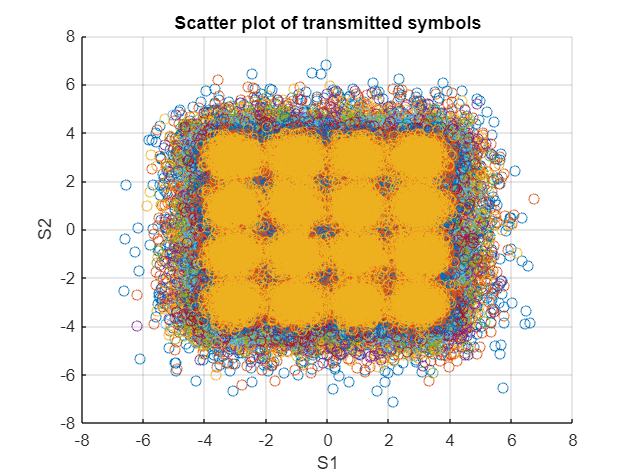

%%dBN=SNR value in dB.
%%Limit of SNR.
s=10 ;
%%error=array to store errors at each SNR.
bitError=zeros(1,s) ;
for dBN=1:s
    var = (10/4)/10^(0.1*(dBN-1));
    noiseX = sqrt(var/2).*randn(n,1) ;
    noiseY = sqrt(var/2).*randn(n,1) ;
    i=1:n ; 
    y= ss ;
    y(i,1) = ss(i,1)+noiseX(i) ;
    y(i,2) = ss(i,2)+noiseY(i) ;
    
    hold on  
    grid on
    title("Scatter plot of transmitted symbols")
    xlabel("S1")
    ylabel("S2")
        i=1:n ;
        scatter(y(i,1),y(i,2)) ;
    hold off ;

Demodulating the received signal :(Demodulation)

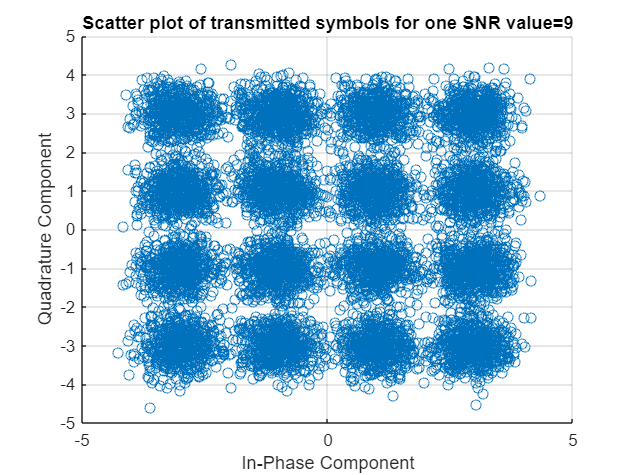

%estimating symbols
    sest=y ;
    for i=1:n
        if y(i,1)<-2 && y(i,2)<-2
            sest(i,1)=-3 ;sest(i,2)=-3 ;
        elseif y(i,1)<-2 && y(i,2)>-2 && y(i,2)<0
            sest(i,1)=-3 ;sest(i,2)=-1 ;
        elseif y(i,1)<-2 && 0<y(i,2) && y(i,2)<2
            sest(i,1)=-3 ;sest(i,2)=1 ;
        elseif y(i,1)<-2 && y(i,2)>2 
            sest(i,1)=-3 ;sest(i,2)=3 ;
        elseif -2<y(i,1) && y(i,1)<0 && y(i,2)<-2
            sest(i,1)=-1 ;sest(i,2)=-3 ;
        elseif -2<y(i,1) && y(i,1)<0 && -2<y(i,2) && y(i,2)<0
            sest(i,1)=-1 ;sest(i,2)=-1 ;
        elseif -2<y(i,1) && y(i,1)<0 && 0<y(i,2) && y(i,2)<2
            sest(i,1)=-1 ;sest(i,2)=1 ;
        elseif -2<y(i,1) && y(i,1)<0 && y(i,2)>2
            sest(i,1)=-1 ;sest(i,2)=3 ;
        elseif 0<y(i,1) && y(i,1)<2 && y(i,2)<-2
            sest(i,1)=1 ;sest(i,2)=-3 ;
        elseif 0<y(i,1) && y(i,1)<2 && -2<y(i,2) && y(i,2)<0
            sest(i,1)=1 ;sest(i,2)=-1 ;
        elseif 0<y(i,1) && y(i,1)<2 && 0<y(i,2) && y(i,2)<2
            sest(i,1)=1 ;sest(i,2)=1 ;
        elseif 0<y(i,1) && y(i,1)<2 && 2<y(i,2)
            sest(i,1)=1 ;sest(i,2)=3 ;
        elseif 2<y(i,1) && y(i,2)<-2
            sest(i,1)=3 ;sest(i,2)=-3 ;
        elseif 2<y(i,1) && -2<y(i,2) && y(i,2)<0
            sest(i,1)=3 ;sest(i,2)=-1 ;
        elseif 2<y(i,1) && 0<y(i,2) && y(i,2)<2
            sest(i,1)=3 ;sest(i,2)=1 ;
        elseif 2<y(i,1) && y(i,2)>2
            sest(i,1)=3 ;sest(i,2)=3 ;
        end
    end
    for i=1:n
        if sest(i,1)==-3 && sest(i,2)==-3
            mest(i,1)=0;mest(i,2)=0;mest(i,3)=0;mest(i,4)=0;
        elseif sest(i,1)==-3 && sest(i,2)==-1
            mest(i,1)=0;mest(i,2)=0;mest(i,3)=0;mest(i,4)=1;
        elseif sest(i,1)==-3 && sest(i,2)==1
            mest(i,1)=0;mest(i,2)=0;mest(i,3)=1;mest(i,4)=0;
        elseif sest(i,1)==-3 && sest(i,2)==3
            mest(i,1)=0;mest(i,2)=0;mest(i,3)=1;mest(i,4)=1;
        elseif sest(i,1)==-1 && sest(i,2)==-3
            mest(i,1)=0;mest(i,2)=1;mest(i,3)=0;mest(i,4)=0;
        elseif sest(i,1)==-1 && sest(i,2)==-1
            mest(i,1)=0;mest(i,2)=1;mest(i,3)=0;mest(i,4)=1;
        elseif sest(i,1)==-1 && sest(i,2)==1
            mest(i,1)=0;mest(i,2)=1;mest(i,3)=1;mest(i,4)=0;
        elseif sest(i,1)==-1 && sest(i,2)==3
            mest(i,1)=0;mest(i,2)=1;mest(i,3)=1;mest(i,4)=1;
        elseif sest(i,1)==1 && sest(i,2)==-3
            mest(i,1)=1;mest(i,2)=0;mest(i,3)=0;mest(i,4)=0;
        elseif sest(i,1)==1 && sest(i,2)==-1
            mest(i,1)=1;mest(i,2)=0;mest(i,3)=0;mest(i,4)=1;
        elseif sest(i,1)==1 && sest(i,2)==1
            mest(i,1)=1;mest(i,2)=0;mest(i,3)=1;mest(i,4)=0;
        elseif sest(i,1)==1 && sest(i,2)==3
            mest(i,1)=1;mest(i,2)=0;mest(i,3)=1;mest(i,4)=1;
        elseif sest(i,1)==3 && sest(i,2)==-3
            mest(i,1)=1;mest(i,2)=1;mest(i,3)=0;mest(i,4)=0;
        elseif sest(i,1)==3 && sest(i,2)==-1
            mest(i,1)=1;mest(i,2)=1;mest(i,3)=0;mest(i,4)=1;
        elseif sest(i,1)==3 && sest(i,2)==1
            mest(i,1)=1;mest(i,2)=1;mest(i,3)=1;mest(i,4)=0;
        else
            mest(i,1)=1;mest(i,2)=1;mest(i,3)=1;mest(i,4)=1;
        end    
    end
    for i=1:n 
        if mest(i,1)~=data(i,1) 
            bitError(dBN)=bitError(dBN)+1 ;
        end
        if mest(i,2)~=data(i,2)
            bitError(dBN)=bitError(dBN)+1 ;
        end
        if mest(i,3)~=data(i,3)
            bitError(dBN)=bitError(dBN)+1 ;
        end
        if mest(i,4)~=data(i,4)
            bitError(dBN)=bitError(dBN)+1 ;
        end
    end
end
    i=1:n ;
    scatter(y(i,1),y(i,2)) ;
title("Scatter plot of transmitted symbols for one SNR value=9")
xlabel("In-Phase Component") 
ylabel("Quadrature Component")
grid on 
%set(gca,'color',[0.1 0.1 0.1])

Calculation of errors and analysis 

disp('Experimental Bit Error Rates:')

Experimental Bit Error Rates:


BER=bitError/(4*n) 

BER =     0.1834    0.1613    0.1311    0.1042    0.0787    0.0565    0.0351    0.0238    0.0132    0.0058


SNR=zeros(1,s) ;
for i=1:s
    SNR(i)=i-1 ;
end

theo=zeros(1,s) ;
for dBN=1:1:s
    var = (10/4)/10^(0.1*(dBN-1));
    theo(dBN)=(3/8)*erfc(sqrt((10)/(10*var))) ;
end
disp('Theoretical Bit-Error rates:') ;

Theoretical Bit-Error rates:


theo

theo =     0.1392    0.1183    0.0976    0.0774    0.0586    0.0419    0.0279    0.0170    0.0092    0.0044


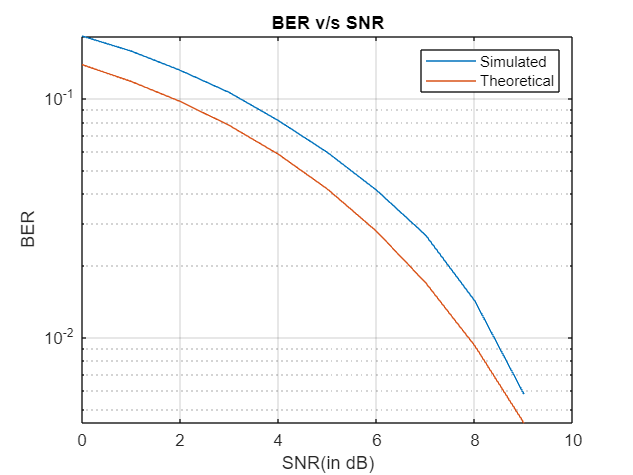

semilogy(SNR,smooth(BER)) ;
hold on  ;
grid on ;
semilogy(SNR,theo) ;
%semilogy(SNR,theo2) ;
hold off;
title("BER v/s SNR")
xlabel("SNR(in dB)")
ylabel("BER")
legend("Simulated","Theoretical");